# kgme - single fish

## load data structure

IN LAB

%load("/Volumes/Elements/kg.mat");
load("/Users/eric/Documents/MATLAB/kgtest2.mat");
addpath('/Users/eric/SparkleShare/github.com/FishCodeGH/Gallman/');

AT HOME

load("/Volumes/Elements/kg.mat");
addpath("/Users/kathryngallman/SparkleShare/github.com/FishCodeGH/Gallman");

## save data structure

IN LAB

save("/Users/eric/Documents/MATLAB/kgtest2.mat", "kg");
%save("/Volumes/Elements/kg.mat", 'kg');

AT HOME

save("/Users/kathryngallman/Documents/MATLAB/kgbackup.mat", "kg");
%save("/Volumes/Elements/kg.mat", 'kg');

## reference raw data folder and asign k value

%raw data files live on the MyBook. Thankfully... ugh.
cd("/Volumes/My Book/Gallman/124LD/Lydia124-Nov-04-2021-C/");

k = 71;

k = 1,2;           4:4 LD

k = 3-5;           48:48 LD 

k = 6, 7;          10:10 LD

k = 8, 9           6:6 LD

      k = 9 - time shifty

k = 10, 11;       24:24 LD

k = 12-17;       12:12 LD

    k=13 - two different fish (pepper then potts) - need to separate

    k = 15 very short and shitty

k = 18-20         5:5 LD

    k = 18 - shit data. replaced Eigen05-Nov-8-2020-A with new poweridx from k = 19;

    k = 20 - just weird. don't use light timers they shift

k = 21 - Eugene 

k = 22   Eugene 12:12 LD - wrong folder label - from super old data - spring 2020 Eigen

k = 23 - Milo

k = 24 - fish run - not sure which fish - need to check

k = 25-27         8:8 LD

k = 28-31        13:13 LD

    k = 29 - don't use. data is backwards

    k = 30 - if trimmed and then outlier removed could salvage data - needs multiple power idxs

    k = 31 - needs second poweridx for channel 1 data - not sure about numberings yet

k = 32-34        6:6 LD

    k = 34 - weird data. backwards

k = 35, 36       8:8 LD

k = 37-40        20:20 LD

    k = 39 - salvagable, needs to be trimmed and outliered.  

k = 41-43        16:16 LD - kinda shitty tbh

k = 44-49         48:48 LD

    k = 45, 49 just not good

k = 50-53         XX temp exp (code 99 for ld)

k = 54, 55        4:4 LD

    k = 54 ch 1 only

    k = 55 ch 2 only

k = 56, 57        24:24 LD - some problems with electrodes

k = 58, 59        5:5 LD

    k = 59 outlier fish - super huge amplitude oscillations

k = 60, 61        10:10 LD

    k = 61 outlier fish " "

k = 63               12:12 to 17 to 24... no idea...

k = 64-67        12:12 - 4:4 - 12:12 - 4:4 - 12:12 LD phase exp.

k = 68-71         124 LD same as 64-67 but take 2         

k = 72- 75        124 take 3 (thanksgiving)

                      k = 73, 75 - fish died halfway through

k = 94            13:13 LD; k = 31  DELME

k = 95            10:10 LD; k = 60 different poweridx

k = 96            5:5 LD; k = 58 different poweridx for ch2 data 

k = 97            REPLACE - OUTLIER FISH PIDX  

k = 98            12:12 LD  

k = 99            6:6 LD; k = 9 - different poweridx (first bit)  

k = 100  k = 17 (need to split)

k = 100, 101            13:13 LD ; k = 31 different power idx DELME

## generate amplitude data

kg(k).e = KatieAssembler('Eigen*', 40000, 23);
%kg(k).e = KatieAssembler('Eigen*', 20000, 22); %really old data
%kg(k).e = KatieAssembler('Eigen*', 40000, 24); %Katie is bad at typing...

## initial plotter

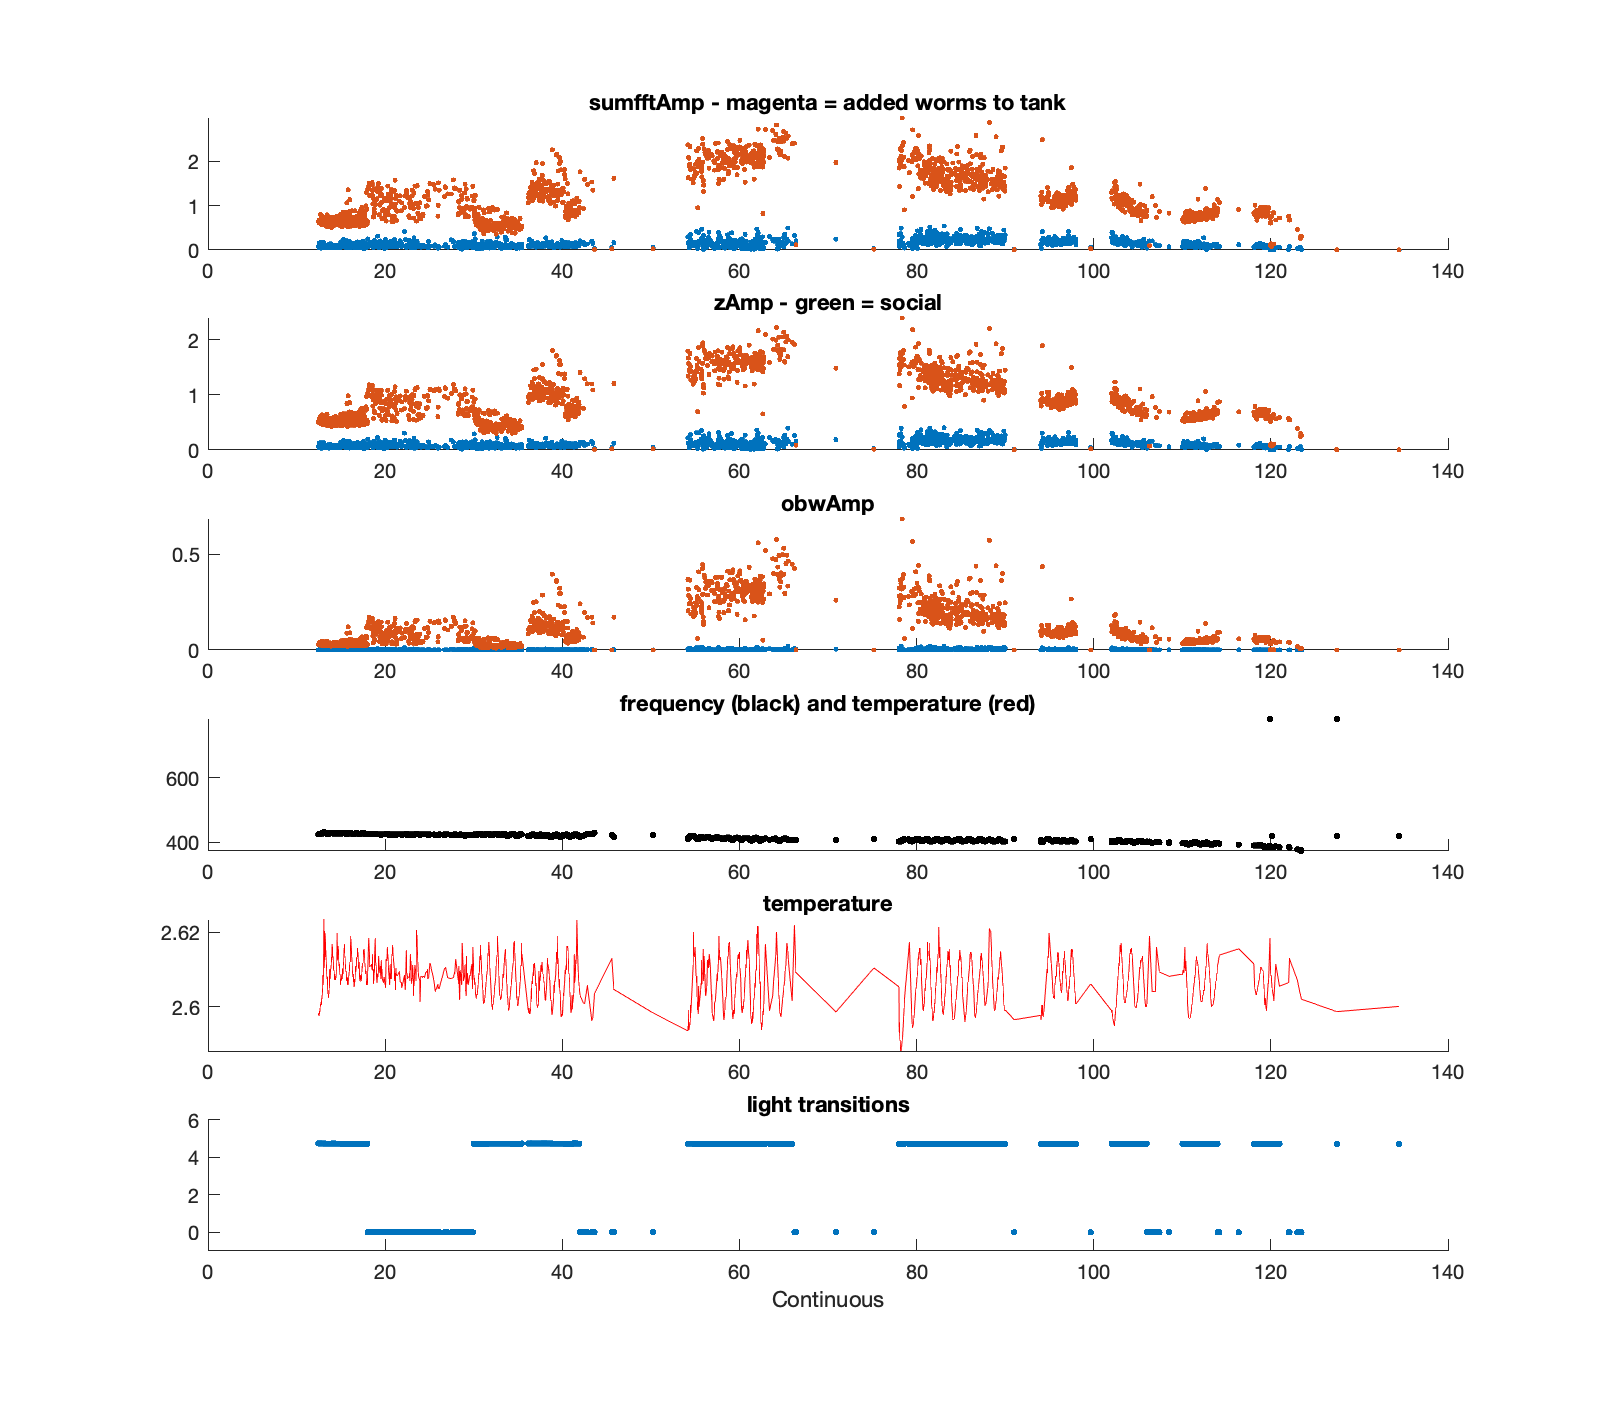

k_initialplotter(kg(k));

## edits

#### trim data

extra step in case of instant clicking regret...

tempdata = KatieTrimmer(kg(k).e);

if before was on purpose 

kg(k).e = tempdata;

#### Remove outliers

Must be redone after trimming

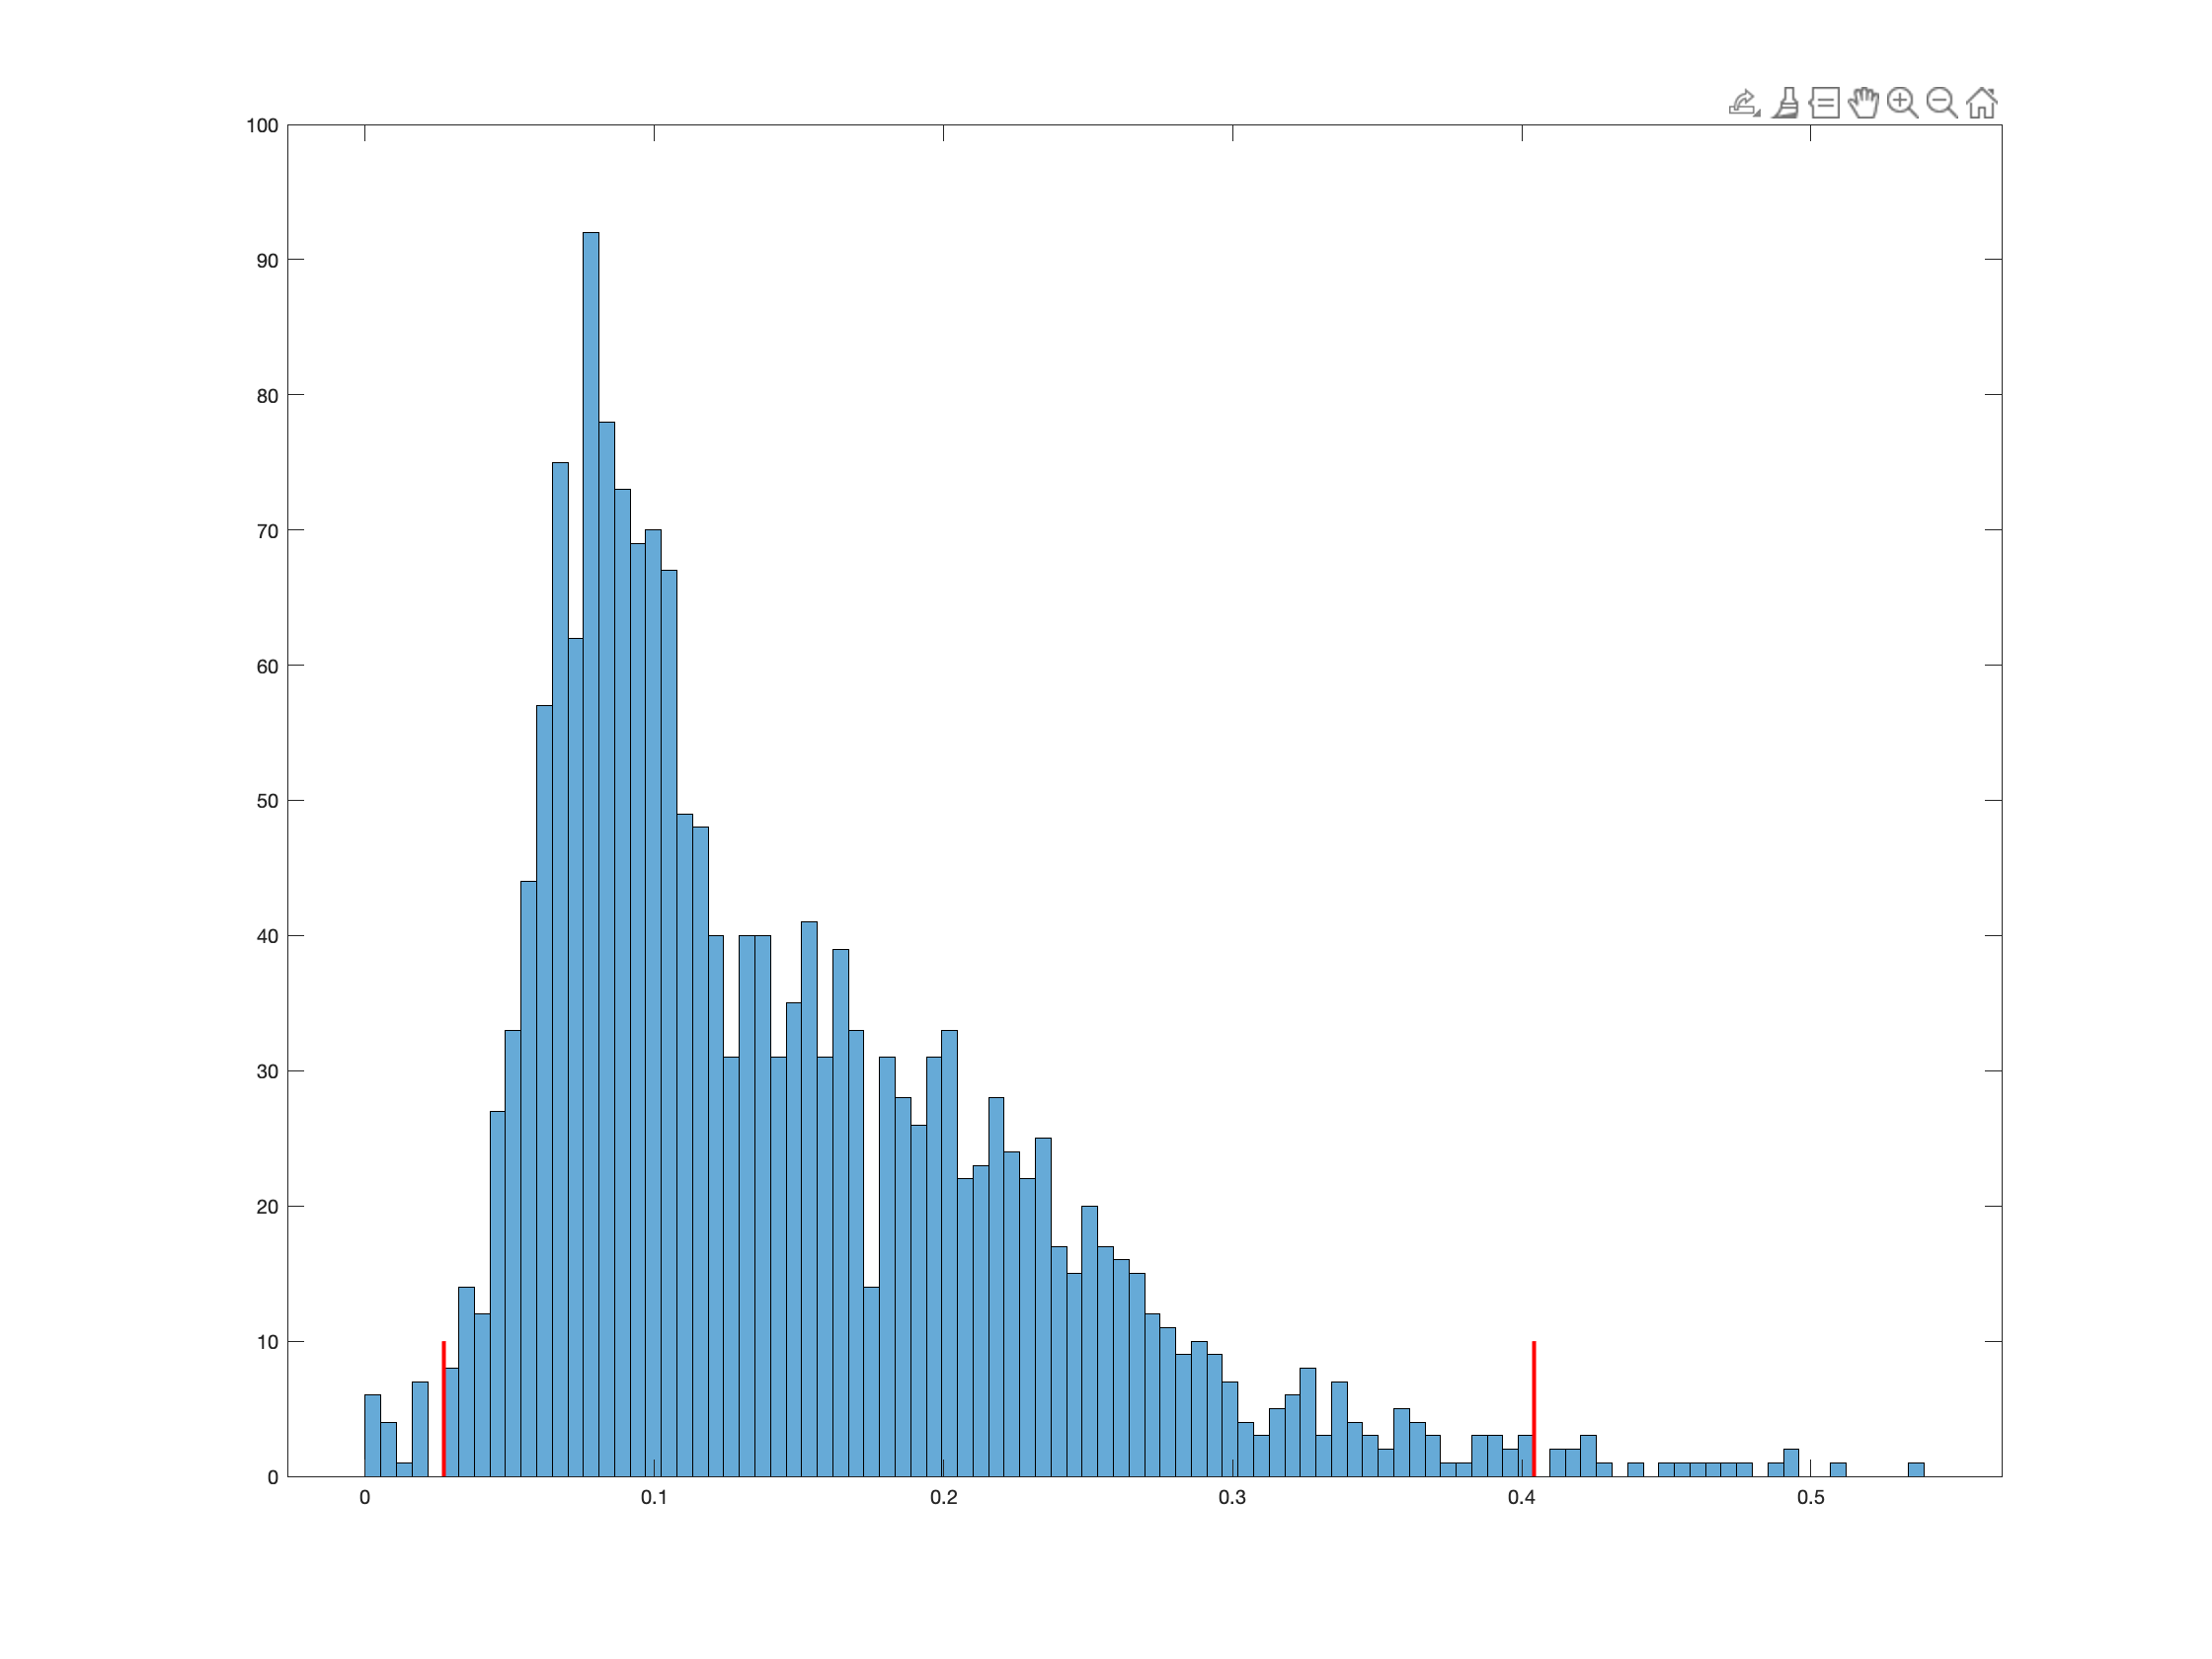

kg(k).idx = KatieRemover(kg(k).e);

## Label

#### light experiment

manual entry into command line - click in window 

kg(k).info = KatieLabeler(kg(k).e);

#### temperature experiment

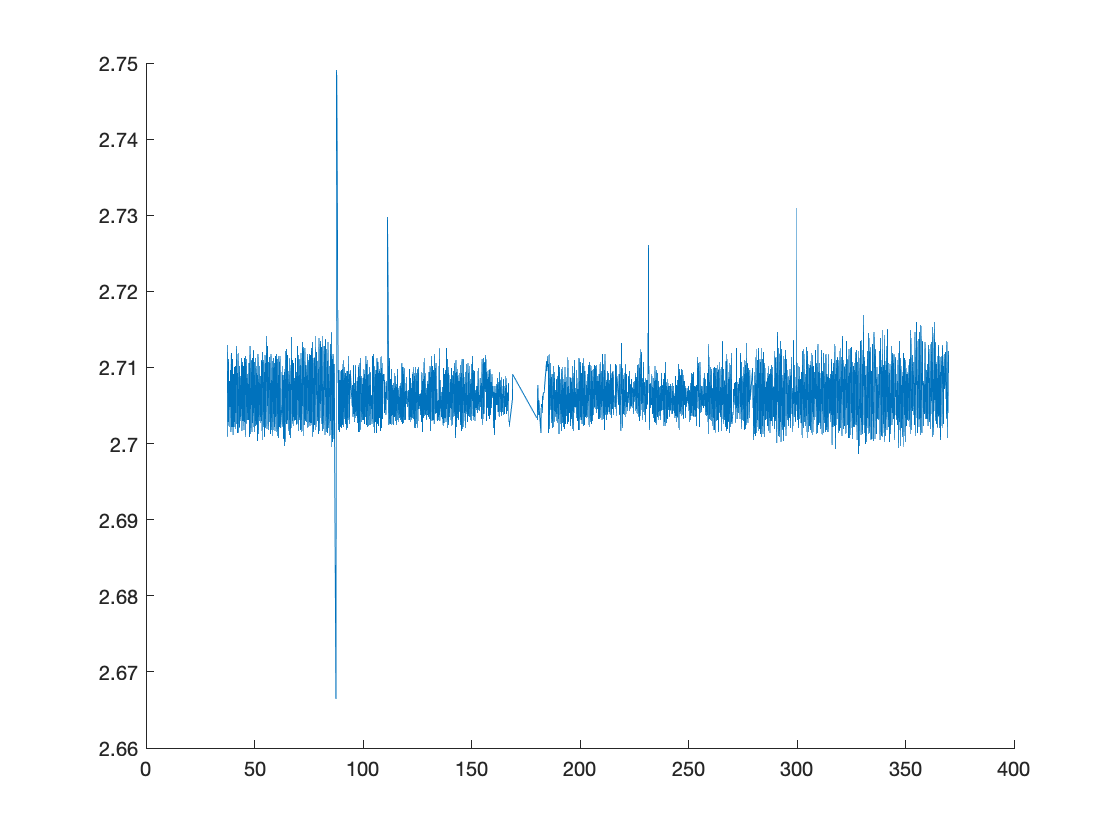

kg(k).info = KatieTempLabeler(kg(k).e);

## initial plotter

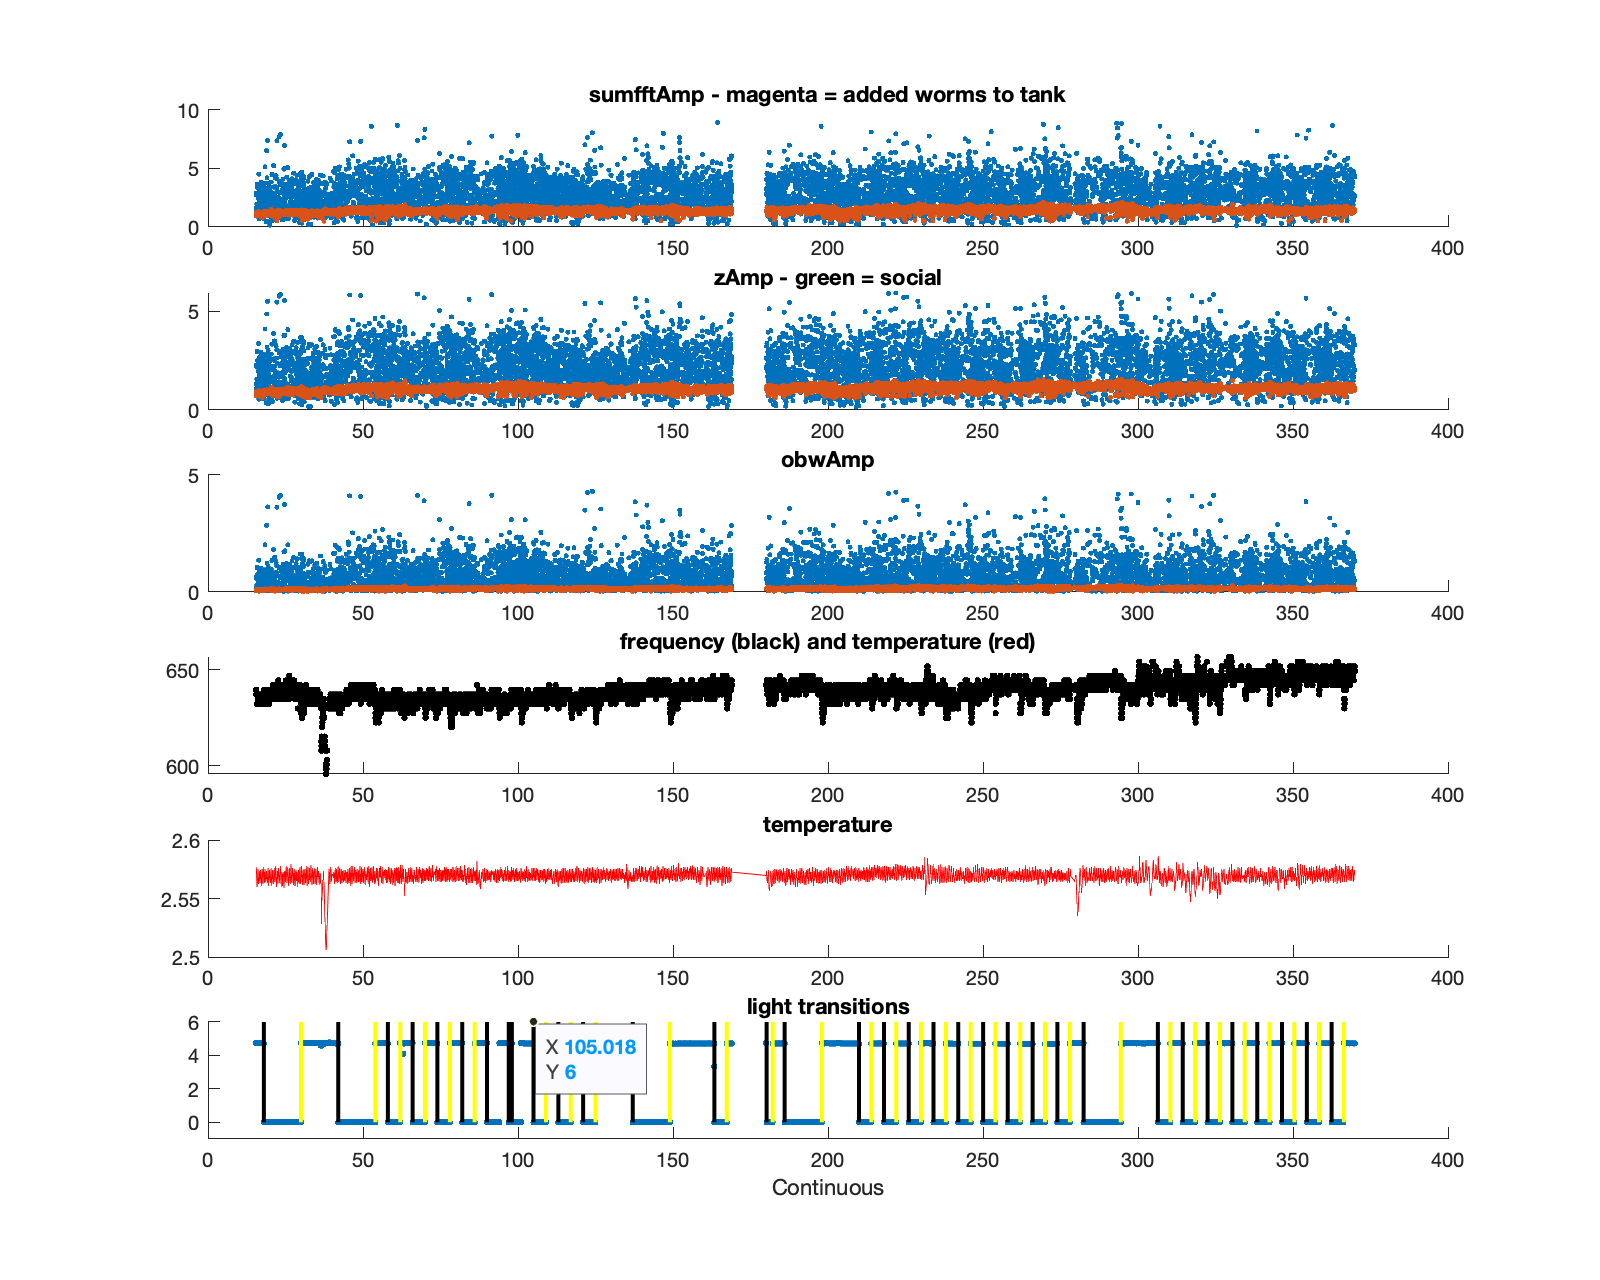

k_initialplotter(kg(k));


kg(98).e(1) = kg(101).e(2);
kg(98).e(2) = kg(101).e(1);

## Fixes

for kk = 1:length(kg(k).info.luz)
    
    if kg(k).info.luz(kk) > 94 && kg(k).info.luz(kk) < 102
        kg(k).info.luz(kk) = [];
    end

end

Index exceeds the number of array elements. Index must not exceed 73.


kg(k).info.luz = [kg(k).info.luz(1:14) 98 kg(k).info.luz(15:end)];

for kk = 1:length([kg(71).e(2).s.timcont])

    kg(71).e(2).s(kk).timcont = kg(71).e(2).s(kk).timcont + (24*3600);
end

for kk = 1:length([kg(71).e(1).s.timcont])

    kg(71).e(1).s(kk).timcont = kg(71).e(1).s(kk).timcont + (24*3600);
end

# Multiple fish

## load data

%load("/Volumes/Elements/kg2.mat");
load("/Users/eric/Documents/MATLAB/kg2backup.mat");

## save data structure

IN LAB

save("/Users/eric/Documents/MATLAB/kg2backup.mat", "kg2");
%save("/Volumes/Elements/kg2.mat", 'kg2');

AT HOME

save("/Users/kathryngallman/Documents/MATLAB/kg2backup.mat", "kg2");
%save("/Volumes/Elements/kg2.mat", 'kg2');

# Multiple fish

main difference is that instead of kg.e we have kg.hifreqfish and kg.lowfreqfish 

## reference raw data folder and asign k value

%raw data files live on the MyBook. Thankfully... ugh.
cd("/Volumes/My Book/Gallman/124LD/MultiEigen124-Nov-04-2021-B/");
k = 18;

12:12 LD k = 1-7

k = 1                12:12 LD

k = 2                XX temp - ~30/36 hour dark

k = 3                12:12 LD - make poweridx

k = 4                XX; k = 3 but temp at the end

k = 5                12:12 LD pretty much only have data for light...

k = 6                 12:12 LD same fish as k = 5

k = 7                    same as above?

k = 8                4:4 LD

k = 9                10:10 LD

k = 10               24:24 LD

k = 11                24:24 LD - mostly just a mess

k = 12         48:48 LD same data - k = 12 average currfreq; 

XX

k = 13

k = 15

k = 16        124 (12:12 LD to 4:4 LD to 12:12LD, etc.)

k = 17        sept20 12:12 not worth it - no data

## generate amplitude data

%kg2(k).s = KseparationNoxious('Eigen*');
kg2(k).s = KatieSeparationAnxiety('Eigen*');
kg2(k).fish = KatieFishFinder(kg2(k).s);

## multi plotter

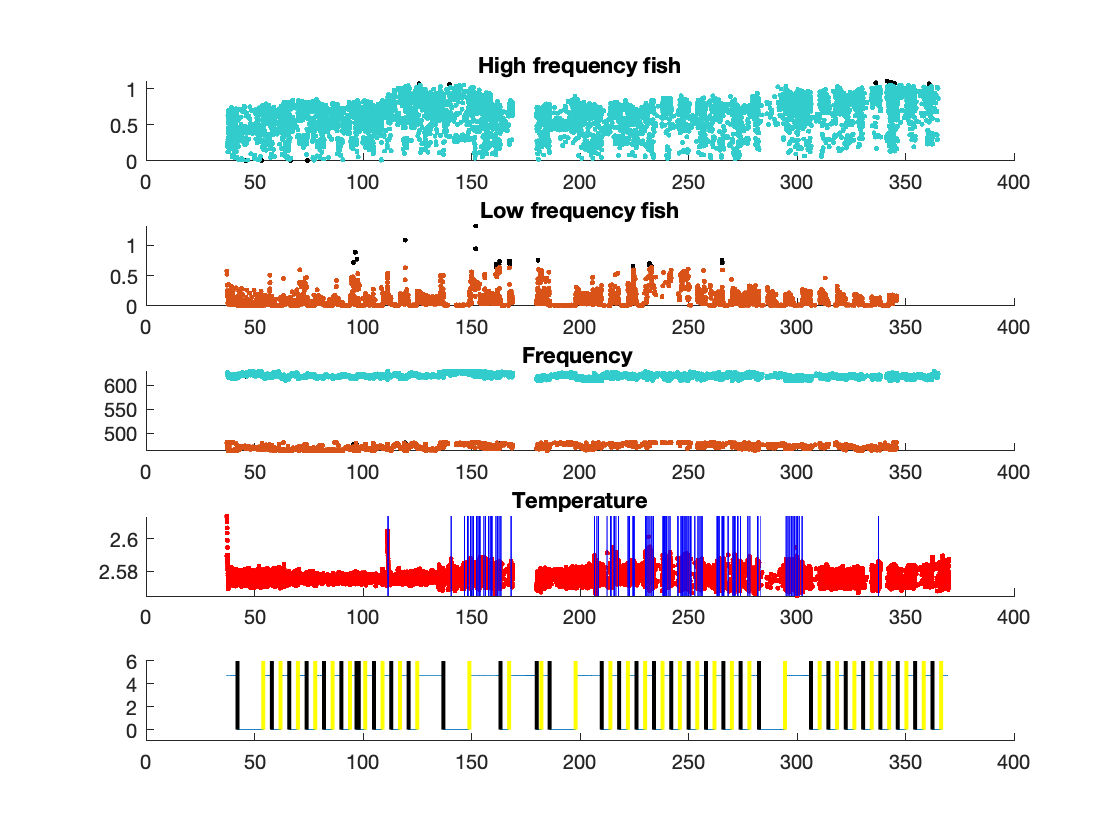

k_multiplotter(kg2(k));

#### Remove outliers

Click cutoff for eliminating erroneously low amplitude measurements.
Click cutoff for eliminating erroneously high amplitude measurements.
Click cutoff for eliminating erroneously low amplitude measurements.
Click cutoff for eliminating erroneously high amplitude measurements.


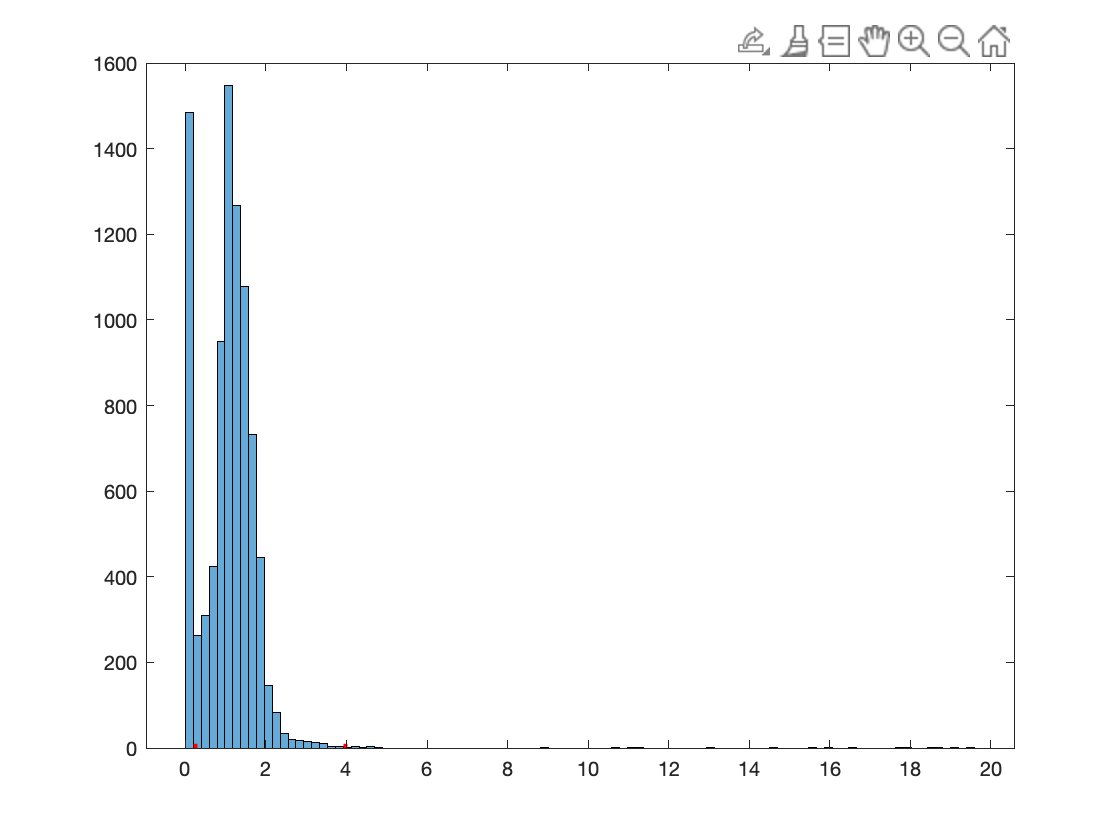

kg2(k).idx = KatieMultiRemover(kg2(k).fish);

#### Label

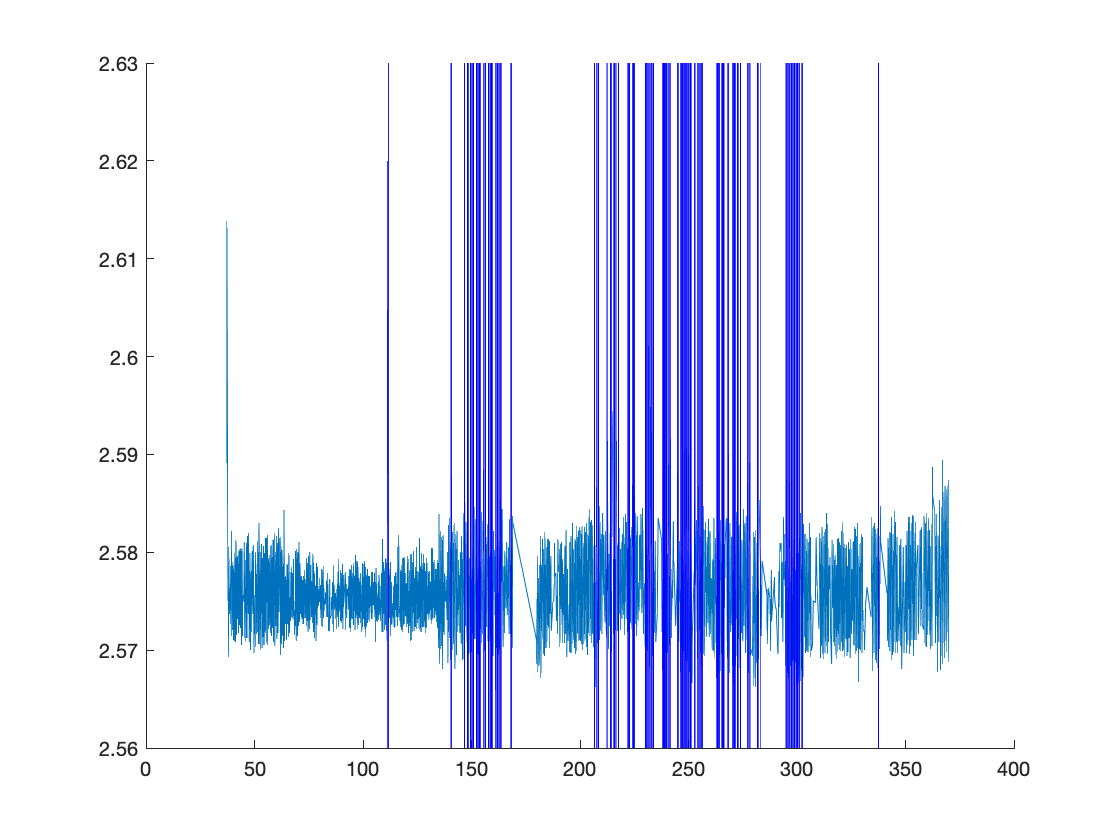

kg2(k).info = KatieMultiLabeler(kg2(k));

#### Fix

%    HiTim = [in.fish.his(tthi).HiTim];
%    HiAmp = [in.fish.his(tthi).HiAmp];
%    LoTim = [in.fish.los(ttlo).LoTim];
%    LoAmp = [in.fish.los(ttlo).LoAmp];

clear kk;
for kk = 1:length([kg2(18).fish.his.HiTim])

    kg2(18).fish.his(kk).HiTim = kg2(18).fish.his(kk).HiTim + 24;

end

clear kk;
for kk = 1:length([kg2(18).fish.los.LoTim])

    kg2(18).fish.los(kk).LoTim = kg2(18).fish.los(kk).LoTim + 24;

end






clear kk;
for kk = 1:length([kg2(18).s.timcont])

    kg2(18).s(kk).timcont = kg2(18).s(kk).timcont + (24*3600);

end



